fs = 1000;
N = 4096*4;
f0 = 20;
fm = 5;
K = 5;
x = zeros(N, 1);
n = 0:N-1;
n = n';
for k = 1:K
    x = x + sin(n*f0*2*pi/fs*k)/k;
end
x(1:N/4) = 0;
x(3*N/4:end) = 0;
x = x.*(0.5 + 0.2*sin(sin(n*fm*2*pi/fs)))

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


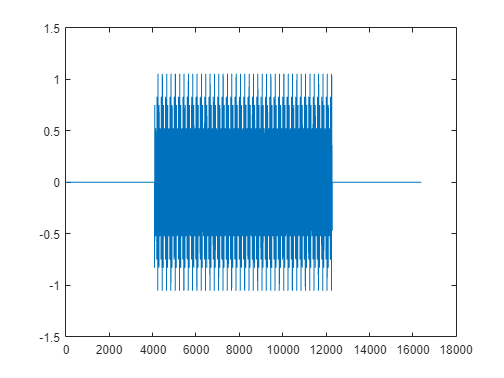

plot(n, x)

fb = SFB(8, 1, fs, N, 10, 400, false);

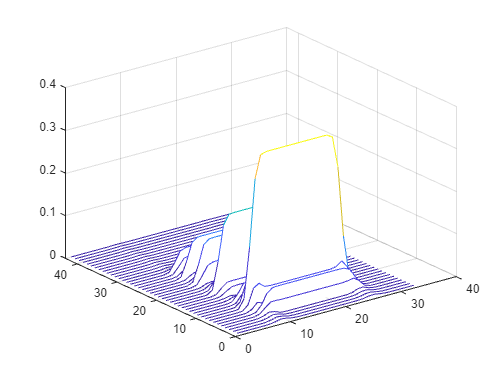

s = fb.filterS(x');
waterfall(s)